# Actividad #3

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

Paso 1: Limpiar variables y linea de comandos

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window
raiz = cd; % Linux command (address current folder)

Paso 2: Crear un codigo basico

% Parámetros
f = 10;         % Frecuencia de la señal en Hz
A1 = 6;          % Amplitud1
A2 = 16;          % Amplitud1
fase1 = 0;      % Fase1
fase2 = 10;     % Fase2
T = 0.25;          % Duración en segundos
fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)
fs = 2000;      % Frecuencia de muestreo en Hz

% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs);
y2 = senal_senoidal(f,A2,fase2,T,fs);

Paso 3: Mostrar resultados con plot

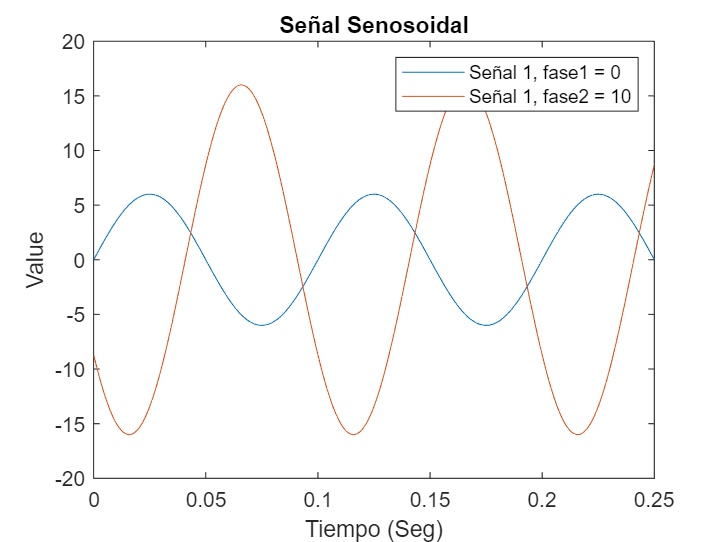

t = 0:1/fs:T;
figure
plot(t,y1) %Señal 1
hold on
plot(t,y2) %Señal 2
title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")
legend("Señal 1, fase1 = 0", "Señal 1, fase2 = 10")